clear all;
close all;
% TODO: Data reshaping 
% TODO: Assign the numeric representations for each cluster
% TODO: Silhouette plot to determine optimal k
% TODO: Implement replicates for kmeans
% TODO: Implement outlier detection

## In this script, you need to implement three functions as part of the k-means algorithm.

These steps will be repeated until the algorithm converges:

  % 1. initialize_centroids
  % This function sets the initial values of the centroids
  
  % 2. assign_vector_to_centroid
  % This goes through the collection of all vectors and assigns them to
  % centroid based on norm/distance
  
  % 3. update_centroids
  % This function updates the location of the centroids based on the collection
  % of vectors (handwritten digits) that have been assigned to that centroid.

## Initialize Data Set

These next lines of code read in two sets of MNIST digits that will be used for training and testing respectively.

% training set (1500 images)
train=csvread('mnist_train_1500.csv');
trainsetlabels = train(:,785);
train=train(:,1:784);
train(:,785)=zeros(1500,1);

% testing set (200 images with 11 outliers)
test=csvread('mnist_test_200_woutliers.csv');
% store the correct test labels
correctlabels = test(:,785);
test=test(:,1:784);

% now, zero out the labels in "test" so that you can use this to assign
% your own predictions and evaluate against "correctlabels"
% in the 'cs1_mnist_evaluate_test_set.m' script
test(:,785)=zeros(200,1);

## After initializing, you will have the following variables in your workspace:

1. train (a 1500 x 785 array, containins the 1500 training images) 2. test (a 200 x 785 array, containing the 200 testing images) 3. correctlabels (a 200 x 1 array containing the correct labels (numerical meaning) of the 200 test images

## To visualize an image, you need to reshape it from a 784 dimensional array into a 28 x 28 array.

to do this, you need to use the reshape command, along with the transpose operation. For example, the following lines plot the first test image

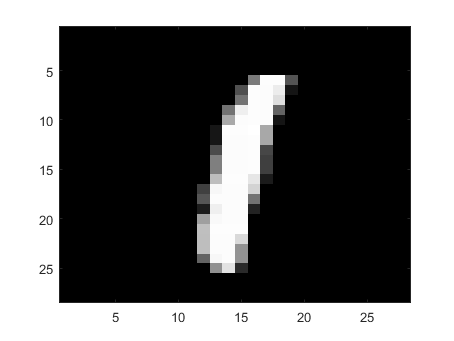

figure;
colormap('gray'); % this tells MATLAB to depict the image in grayscale
testimage = reshape(test(1, [1:784]), [28 28]);
% we are reshaping the first row of 'test', columns 1-784 (since the 785th
% column is going to be used for storing the centroid assignment.
imagesc(testimage'); % this command plots an array as an image.  Type 'help imagesc' to learn more.

## After importing, the array 'train' consists of 1500 rows and 785 columns.

Each row corresponds to a different handwritten digit (28 x 28 = 784) plus the last column, which is used to index that row (i.e., label which cluster it belongs to. Initially, this last column is set to all zeros, since there are no clusters yet established.

## This next section of code calls the three functions you are asked to specify

k= 28; % set k
max_iter= 2000; % set the max number of iterations of the algorithm

## The next line initializes the centroids. Look at the initialize_centroids()

function, which is specified further down this file.

centroids=initialize_centroids(train,k);

## Initialize an array that will store k-means cost at each iteration

cost_iteration = zeros([max_iter,1]);

## This for-loop enacts the k-means algorithm

% Use k=28 with +- 5 range
minK = k-5;
maxK = k+5;
% Store the cost function + prediction accuracy of each k value
minCosts = zeros([maxK-minK+1,1]);
accuracies = zeros([maxK-minK+1,1]);
% Store the locations of the best centroids
maxCentroidScore = -1000;
maxCentroidLocations = zeros(size(maxK,1),785);
accuracy = 0;
% This is to avoid a later problem where splitapply does not accept vectors
% with 0s in them (sparse vectors). Just remember to subtract 1 from the
% group numbers to get the actual numerical value each group (index) represents
trainsetlabels = trainsetlabels + 1;
for k=minK:maxK
    % Initialize centroids randomly
    centroids=initialize_centroids(train,k);
    cost_iteration = zeros([max_iter,1]);
    iterUsed = max_iter;
    
    for iter=1:max_iter
        % Assign the vectors to centroids
        for j=1:size(train,1)
            [index,vec_distance] = assign_vector_to_centroid(train(j,:),centroids);
            cost_iteration(iter) = cost_iteration(iter) + vec_distance;
            train(j,785) = index;
        end
        
        new_centroids = update_Centroids(train,k);
        % If the new centroids are the same as old...
        if(centroids(:,1:784)==new_centroids)
            fprintf("Converged, k=%d at iteration %d",k,iter)
            iterUsed = iter;
            break;
        end
        
        centroids(:,1:784) = new_centroids;
    end
    

    % Assess the accuracy of the k-means
    centroid_labels = splitapply(@mode,trainsetlabels,train(:,785))-1;
    numCorrect = 0;
    testResults = zeros(size(test,1),1);
    for t=1:size(test,1)
        testResults(t) = centroid_labels(predict(centroids,test(t,1:784)));
        if(testResults(t)==correctlabels(t))
            numCorrect = numCorrect + 1;
        end
    end
    accuracies(k+1-minK) = numCorrect;
    fprintf(" %d Correct\n",numCorrect);
    minCosts(k+1-minK) = min(cost_iteration(1:iterUsed));
    if(numCorrect-0.5*k > maxCentroidScore)
        maxCentroidLocations = centroids;
        accuracy = numCorrect;
    end
end

Converged, k=23 at iteration 29

 141 Correct


Converged, k=24 at iteration 24

 143 Correct


Converged, k=25 at iteration 19

 133 Correct


Converged, k=26 at iteration 15

 143 Correct


Converged, k=27 at iteration 23

 145 Correct


Converged, k=28 at iteration 35

 154 Correct


Converged, k=29 at iteration 16

 142 Correct


Converged, k=30 at iteration 15

 147 Correct


Converged, k=31 at iteration 19

 141 Correct


Converged, k=32 at iteration 13

 149 Correct


Converged, k=33 at iteration 18

 149 Correct


accuracies = cat(2,(minK:maxK).',accuracies);

## This section of code plots the k-means cost as a function of the number of iterations

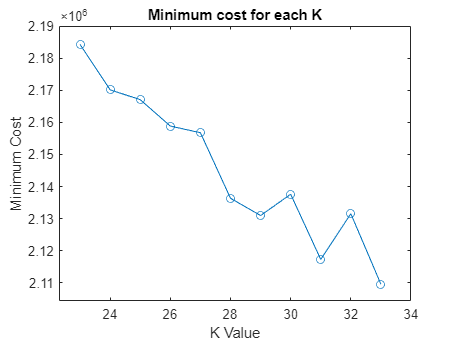

% Plot the cost function vs K
figure;
plot(minK:maxK,minCosts(1:maxK-minK+1),'o-');
title("Minimum cost for each K")
xlabel("K Value")
ylabel("Minimum Cost")
axis padded

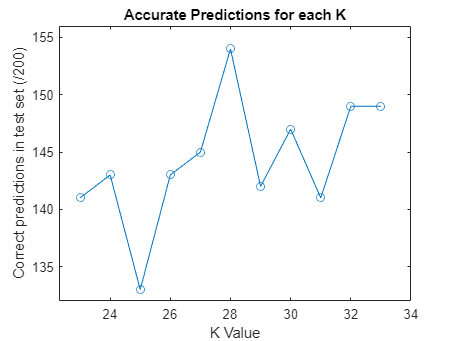


% Plot the accuracy of the models vs K
figure;
plot(accuracies(:,1),accuracies(:,2),'o-')
title("Accurate Predictions for each K")
xlabel("K Value")
ylabel("Correct predictions in test set (/200)")
axis padded

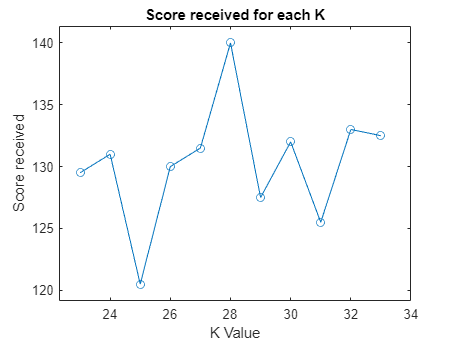


% Plot the scores awarded vs K
scoreRcvd = accuracies;
scoreRcvd(:,2) = scoreRcvd(:,2) - scoreRcvd(:,1)*0.5;
figure;
plot(scoreRcvd(:,1),scoreRcvd(:,2),'o-');
title("Score received for each K")
xlabel("K Value")
ylabel("Score received")
axis padded

[~,k] = max(scoreRcvd(:,2));
k = scoreRcvd(k,1);
fprintf("K=%d gives the greatest score: Accuracy %d",k,accuracies(k-minK+1,2));

K=28 gives the greatest score: Accuracy 154

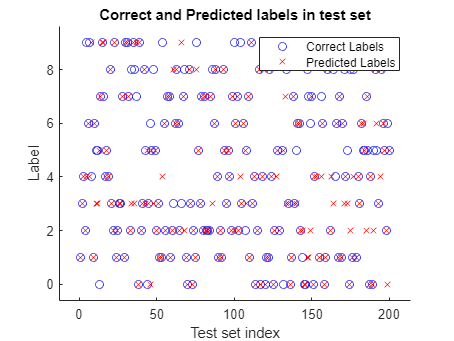


% Show the correct vs predicted labels for the best model
figure;
hold on
scatter(1:size(correctlabels),correctlabels,'bo')
scatter(1:size(testResults),testResults,'xr')
hold off
title("Correct and Predicted labels in test set")
xlabel("Test set index")
ylabel("Label")
legend(["Correct Labels" "Predicted Labels"])
axis padded

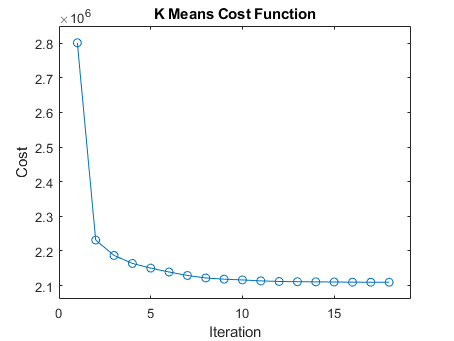


% Show the cost of the best model as the iterations progress
figure;
plot(cost_iteration(1:iterUsed),'o-')
title("K Means Cost Function")
xlabel("Iteration")
ylabel("Cost")
axis padded

## This next section of code will make a plot of all of the centroids

Again, use help [functionname](about:blank<#functionname>) to learn about the different functions that are being used here.

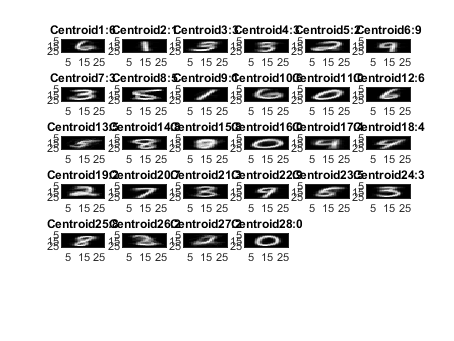

figure;
colormap('gray');

plotsize = ceil(sqrt(k));

for ind=1:k
    centr=centroids(ind,[1:784]);
    subplot(plotsize,plotsize,ind);
    
    imagesc(reshape(centr,[28 28])');
    title(strcat('Centroid ',num2str(ind),':',num2str(centroid_labels(ind))))
end

save("classifierdata.mat","centroids","centroid_labels")

## Functions to predict results based on a set of centroids

function result=predict(centroids,point)
    % Predict result using euclidean distance
    minIndex = 1;
    for i=1:size(centroids,1)
        if(norm(centroids(i,1:784)-point)<norm(centroids(minIndex,1:784)-point(1:784)))
            
            minIndex = i;
            
        end
        
    end
    result = minIndex;
    
end
% 
% % [results, accuracy]
% function results=checkResults(centroids,points,groundtruth)
%     
%     r=ones([size(points,1),2]);
%     
%     % 1:size(points,1)
%     for j=1:200
%         r(j:2) = predict(centroids,points(j,:));
%         r(j:1) = j;
%     end
%     
%     positives = (r==groundtruth);
%     accuracy = sum(positives)/length(positives);
%     results = r;
% end

## Function to initialize the centroids

This function randomly chooses k vectors from our training set and uses them to be our initial centroids There are other ways you might initialize centroids. *Feel free to experiment.*** Note that this function takes two inputs and emits one output (y).

function y=initialize_centroids(data,num_centroids)

random_index=randperm(size(data,1));

centroids=data(random_index(1:num_centroids),:);

y=centroids;

end

## Function to pick the Closest Centroid using norm/distance

This function takes two arguments, a vector and a set of centroids It returns the index of the assigned centroid and the distance between the vector and the assigned centroid.

function [index, vec_distance] = assign_vector_to_centroid(data,centroids)
    minC = 1;
    dists = zeros([size(centroids,1),1]);
    for c=1:size(centroids,1)
        dists(c) = norm(data(1:784)-centroids(c,1:784));
        if(dists(minC)>dists(c))
            minC = c;
        end
    end
    index = minC;
    vec_distance = dists(minC);
end

## Function to compute new centroids using the mean of the vectors currently assigned to the centroid.

This function takes the set of training images and the value of k. It returns a new set of centroids based on the current assignment of the training images.

function new_centroids=update_Centroids(data,K)
    new_centroids = splitapply(@mean,data(:,1:784),data(:,785));
end